rng default % para que sea reproducible
d = linspace(0,3);
y = exp(-1.3*d) + 0.05*randn(size(d));
fun = @(r)exp(-d*r)-y;
x0 = 4;

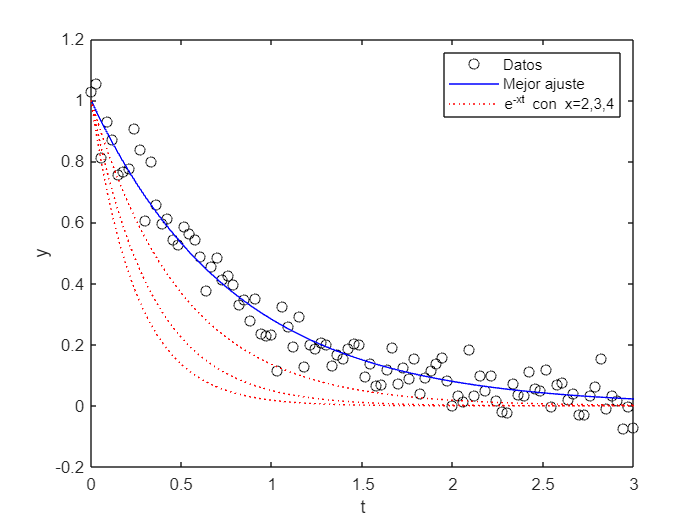

x = myLevMar(fun,x0);
plot(d,y,'ko',d,exp(-x*d),'b-',d,exp(-4*d),'r:',d,exp(-3*d),'r:',d,exp(-2*d),'r:')
legend('Datos','Mejor ajuste','e^{-xt} con x=2,3,4')
xlabel('t')
ylabel('y')

x2 = lsqnonlin(fun,x0)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x2 = 1.2645

[x, info]=myLevMar(fun,x0)

Array indices must be positive integers or logical values.

Error in myLevMar (line 33)
        int(nulls) = nulls+1;